% Syntax: Baltic_SDN_BEC_analyses.m (script)
%
% Description
% Analyses of Argo floats as provided by BEC.
% Input: matlab files created from the original netCDF files (use
% ar_rd_BEC.m)
%
% Inputs
% iregion: There are four Baltic+ study regions (see Baltic+ DUM, p. 28):
%          [1] Arkona Basin           [ArB] (55°31'30.22"N,  16°16'15.06"E)
%          [2] Bothian Sea            [BOS] (61°55'50.19"N,  19°14'46.24"E)
%          [3] Gulf of Finland        [GOF] (59°35'55.07"N,  23°07'27.96"E)
%          [4] Northern Baltic Proper [NBP] (57°36'10.05"N,  19°48'25.78"E)
%          [5] ALL-Baltic             [ALL] 
%
%
% This script compares Satellite data againts the Argo (in situ) data.
% Furthermore, this script does compare Argo againts regional model data (NEMO).
% The model data is used in the processing of the new Baltic+ SSS data set.
%
% This script does the following:
% [1] Colocations Argo-2-satellite and Argo-2-Model grid/time [Baltic_SDN_colocations.m]
% [2] Comparisons Argo Vs Satellite and Argo-2-Model
% [3] Baltic Study [2011-2013]:
% *[3.1] BOXPLOTS
% ** [3.1.1] BOXPPLOT: SSS at float location (i.e. SSS-satellite and SSS-model)
% *[3.2] PROFILES: Argo Profiles (T and S) -- study column structure
% *[3.3] TIMESERIES
% ** [3.3.1] SSS Timeseries at float location
% ** [3.3.2] dSSS Timeseries at float location (dSSS = Argo - QD, QD: Query dataset)
%
%
% Data source:
% BEC products for validation
%
%
% current version: v2r1 (2020/03/05) - NEW VERSION
%
% History
%
% [3] Change order of script by:
%     --> 1/ Make daily plots Argo and SSS-satellite;
%     --> 2/ Save daily plots (to study TOP surface melting ice Vs. SSS)
%
% [2] Creation of snipet (functions) to make Argo vertical interpolations
% [1] Creation of this script [20191114]
%
%
% =========================================================================
% Author: rcatany
%
% =========================================================================
warning('off','all')
%clc;
clear;
close all

% Get SSS-satellite data within a given distance from each Argo float
r = 25; % Radius distance platform (in Km)
depth_ref = 10; % Reference depth (m), by gral. assumtion 10 m
ibasin = 9;     % Basin number: 7 (Arctic); 9 (Baltic)
iregion = 5;    % [5] ALL-BALTIC; see top of the script for other options
iyear = 2011:2013;
imonth = 1:12;

% Define first and last year of timeseries (stings)
year1_str = num2str(iyear(1));
year2_str = num2str(iyear(end));

% get basin limits
[xmin,xmax,ymin,ymax, basin_str] = map_lim_raf(ibasin);


% Colocatiion fn_out for each Regional study in the Baltic
if strcmpi(iregion,'ARB') || iregion == 1% Arkona Basin
    region = 'ARB';
    
elseif strcmpi(iregion,'BOS') || iregion == 2 % Bothian Sea
    region = 'BOS';
    
elseif strcmpi(iregion,'GOF') || iregion == 3 % Gulf of Finland
    region = 'GOF';
    
elseif strcmpi(iregion,'NBP') || iregion == 4 % Gulf of Finland
    region = 'NBP';
    
elseif strcmpi(iregion,'ALL') || iregion == 5 % all-Baltic region stats
    region = 'ALL';
    
end
    

% ==================================
% Folders input/output
fg_save = 1; % flag save figures [1]; or not [0];
fg_format = 'png';

path_root = ('/Volumes/Rogue/Data/');
folder_data = ([path_root ...
    'SSS/' basin_str '/BEC/Validation/indata/SDN/']);

% Make a log_file to record status of each ARGO-BEC file [2020/01/21]
folder_log = ['/Volumes/Rogue/Data/SSS/' basin_str '/BEC/Validation/indata/'];
fn_log = [folder_log 'SDN_MISSING_20200121.txt'];

folder_figs = '/Volumes/Rogue/scratch/Validation/';

folder_colocations = [path_root...
    'SSS/Baltic/BEC/Validation/indata/SDN/Colocations/cat_files/' ];

% ==========================


% filename Argo BEC structure: SDN_20110101_20110110.nc
ndays = 9; % number of days contained in each BEC Argo file


folder_figs = [folder_figs basin_str '/SDN/SDN-BEC/'];

if fg_save == 1
    foldercheck_raf(folder_figs); %! make folder_figs
end

## [1] Colocation Argo-2-Satellite (% Baltic_SDN_BEC_colocations.m)

run ([basin_str '_SDN_BEC_colocations.m'])% (snippet)

% Load colocations Argo to different satellites
% [X1] Baltic Nominal
version_col1 = 'v1r0_NOM';
fn_col1 = [folder_colocations version_col1 '/'...
    basin_str '_' region '_SDN_R' num2str(r)...
    '_10m_COLOCATIONS_' year1_str '_' year2_str...
    '_' version_col1 '_STATS' '.mat'];

% [X2] Baltic Nodal sampling v1.0
version_col2 = 'v1r0_NS';
fn_col2 = [folder_colocations version_col2 '/'...
    basin_str '_' region '_SDN_R' num2str(r)...
    '_10m_COLOCATIONS_' year1_str '_' year2_str...
    '_' version_col2 '_STATS' '.mat'];

% [X3] Baltic CCI+SSSv1.7
version_col3 = 'CCI+SSSv1.7';
fn_col3 = [folder_colocations version_col3 '/'...
    basin_str '_' region '_SDN_R' num2str(r)...
    '_10m_COLOCATIONS_' year1_str '_' year2_str...
    '_' version_col3 '_STATS' '.mat'];

% [X4] Baltic Reanalysis (NEMO v003)
version_col4 = 'REANALYSIS_PHY_003_011';
fn_col4 = [folder_colocations version_col4 '/'...
    basin_str '_' region '_SDN_R' num2str(r)...
    '_10m_COLOCATIONS_' year1_str '_' year2_str...
    '_' version_col4 '_STATS' '.mat'];



X1 = load(fn_col1);
X2 = load(fn_col2);
X3 = load(fn_col3);
X4 = load(fn_col4);

## [1.1] Compute Monthly mean

Ideally use median instead of mean (ie. to keep statistical robustness)

% this piece of code could be implemented in the stats function
% (validation_stats)
itime1 = X1.time_irange;
sss1 = nanmedian(X1.sss_irange,1);
SALT_ref1 = X1.SALT_ref;

itime2 = X2.time_irange;
sss2 = nanmedian(X2.sss_irange,1);
SALT_ref2 = X2.SALT_ref;

itime3 = X3.time_irange;
sss3 = nanmedian(X3.sss_irange,1);
SALT_ref3 = X3.SALT_ref;

itime4 = X4.time_irange;
sss4 = nanmedian(X4.sss_irange,1);
SALT_ref4 = X4.SALT_ref;


% remove salinities lower than SSS_min
SSS_min = 0;
ind_1 = sss1<SSS_min;
ind_2 = sss2<SSS_min;
ind_3 = sss3<SSS_min;
ind_4 = sss4<SSS_min;

sss1(ind_1) = NaN;
sss2(ind_2) = NaN;
sss3(ind_3) = NaN;
sss4(ind_4) = NaN;


% ===========================
itime_date1 = datevec(itime1);
itime_date2 = datevec(itime2);
itime_date3 = datevec(itime3);
itime_date4 = datevec(itime4);


% set the limits of the timeseries (ie. it is the same for all dataseries)
year_min = min(itime_date1(:,1));
year_max = max(itime_date1(:,1));
month_min = min(itime_date1(:,2));
month_max = max(itime_date1(:,2));

years = year_min:year_max;
months = month_min:month_max;


time_start = datenum(year_min,month_min,1,0,0,0);
time_end = datenum(year_max,month_max,1,0,0,0);


Nyears = length(years);
Nmonths = length(months);


TT = nan([1,Nyears*Nmonths]);

ncoloc_monthly1 = TT;
sss_monthly_mean1 = TT;
sss_monthly_median1 = TT;
sss_monthly_std1 = TT;
SALT_ref_monthly_mean1 = TT;
SALT_ref_monthly_median1 = TT;
SALT_ref_monthly_std1 = TT;

ncoloc_monthly2 = TT;
sss_monthly_mean2 = TT;
sss_monthly_median2 = TT;
sss_monthly_std2 = TT;
SALT_ref_monthly_mean2 = TT;
SALT_ref_monthly_median2 = TT;
SALT_ref_monthly_std2 = TT;

ncoloc_monthly3 = TT;
sss_monthly_mean3 = TT;
sss_monthly_median3 = TT;
sss_monthly_std3 = TT;
SALT_ref_monthly_mean3 = TT;
SALT_ref_monthly_median3 = TT;
SALT_ref_monthly_std3 = TT;

ncoloc_monthly4 = TT;
sss_monthly_mean4 = TT;
sss_monthly_median4 = TT;
sss_monthly_std4 = TT;
SALT_ref_monthly_mean4 = TT;
SALT_ref_monthly_median4 = TT;
SALT_ref_monthly_std4 = TT;



ncount = 0; % reset loop counter

for yy = 1:Nyears
    for mm = 1:Nmonths
        ncount = ncount+1;
        
        ind1 = itime_date1(:,1) == years(yy) & itime_date1(:,2) == months(mm);
        ind2 = itime_date2(:,1) == years(yy) & itime_date2(:,2) == months(mm);
        ind3 = itime_date3(:,1) == years(yy) & itime_date3(:,2) == months(mm);
        ind4 = itime_date4(:,1) == years(yy) & itime_date4(:,2) == months(mm);
        
        ncoloc_monthly1(ncount) = sum(ind1);
        sss_monthly_mean1(ncount) = nanmean(sss1(ind1));        
        sss_monthly_median1(ncount) = nanmedian(sss1(ind1));
        sss_monthly_std1(ncount) = nanstd(sss1(ind1));
        SALT_ref_monthly_mean1(ncount) = nanmean(SALT_ref1(ind1));
        SALT_ref_monthly_median1(ncount) = nanmedian(SALT_ref1(ind1));
        SALT_ref_monthly_std1(ncount) = nanstd(SALT_ref1(ind1));
        
        ncoloc_monthly2(ncount) = sum(ind2);
        sss_monthly_mean2(ncount) = nanmean(sss2(ind2));        
        sss_monthly_median2(ncount) = nanmedian(sss2(ind2));
        sss_monthly_std2(ncount) = nanstd(sss2(ind2));
        SALT_ref_monthly_mean2(ncount) = nanmean(SALT_ref2(ind2));
        SALT_ref_monthly_median2(ncount) = nanmedian(SALT_ref2(ind2));
        SALT_ref_monthly_std2(ncount) = nanstd(SALT_ref2(ind2));
        
        ncoloc_monthly3(ncount) = sum(ind3);
        sss_monthly_mean3(ncount) = nanmean(sss3(ind3));        
        sss_monthly_median3(ncount) = nanmedian(sss3(ind3));
        sss_monthly_std3(ncount) = nanstd(sss3(ind3));
        SALT_ref_monthly_mean3(ncount) = nanmean(SALT_ref3(ind3));
        SALT_ref_monthly_median3(ncount) = nanmedian(SALT_ref3(ind3));
        SALT_ref_monthly_std3(ncount) = nanstd(SALT_ref3(ind3));

        ncoloc_monthly4(ncount) = sum(ind4);
        sss_monthly_mean4(ncount) = nanmean(sss4(ind4));        
        sss_monthly_median4(ncount) = nanmedian(sss4(ind4));
        sss_monthly_std4(ncount) = nanstd(sss4(ind4));
        SALT_ref_monthly_mean4(ncount) = nanmean(SALT_ref4(ind4));
        SALT_ref_monthly_median4(ncount) = nanmedian(SALT_ref4(ind4));
        SALT_ref_monthly_std4(ncount) = nanstd(SALT_ref3(ind4));
        

    end
    
end

dsss_monthly_mean1 = sss_monthly_mean1 - SALT_ref_monthly_mean1;
dsss_monthly_mean2 = sss_monthly_mean2 - SALT_ref_monthly_mean2;
dsss_monthly_mean3 = sss_monthly_mean3 - SALT_ref_monthly_mean3;
dsss_monthly_mean4 = sss_monthly_mean4 - SALT_ref_monthly_mean4;

dsss_monthly_std1 = sss_monthly_std1 - SALT_ref_monthly_std1;
dsss_monthly_std2 = sss_monthly_std2 - SALT_ref_monthly_std2;
dsss_monthly_std3 = sss_monthly_std3 - SALT_ref_monthly_std3;
dsss_monthly_std4 = sss_monthly_std4 - SALT_ref_monthly_std4;


dsss_monthly_median1 = sss_monthly_median1 - SALT_ref_monthly_median1;
dsss_monthly_median2 = sss_monthly_median2 - SALT_ref_monthly_median2;
dsss_monthly_median3 = sss_monthly_median3 - SALT_ref_monthly_median3;
dsss_monthly_median4 = sss_monthly_median4 - SALT_ref_monthly_median4;

## [2] PLOTS: REF Vs Satellite

## [2.1] Plot: in situ geolocation

Plots in one map locations of same platform

make_plot = 0; % flag to make plot [1], or not [0]
if make_plot == 1
    % snippet to plot map and zoom-in to Argo location
    Baltic_plot_map_SDN_BEC
    
end

## [1.2] Compute bin data (mean,median, std) - [bin of 1 x 1, ie. like in PIMEP]

## [1.2.1] Number of match-up in eah bin

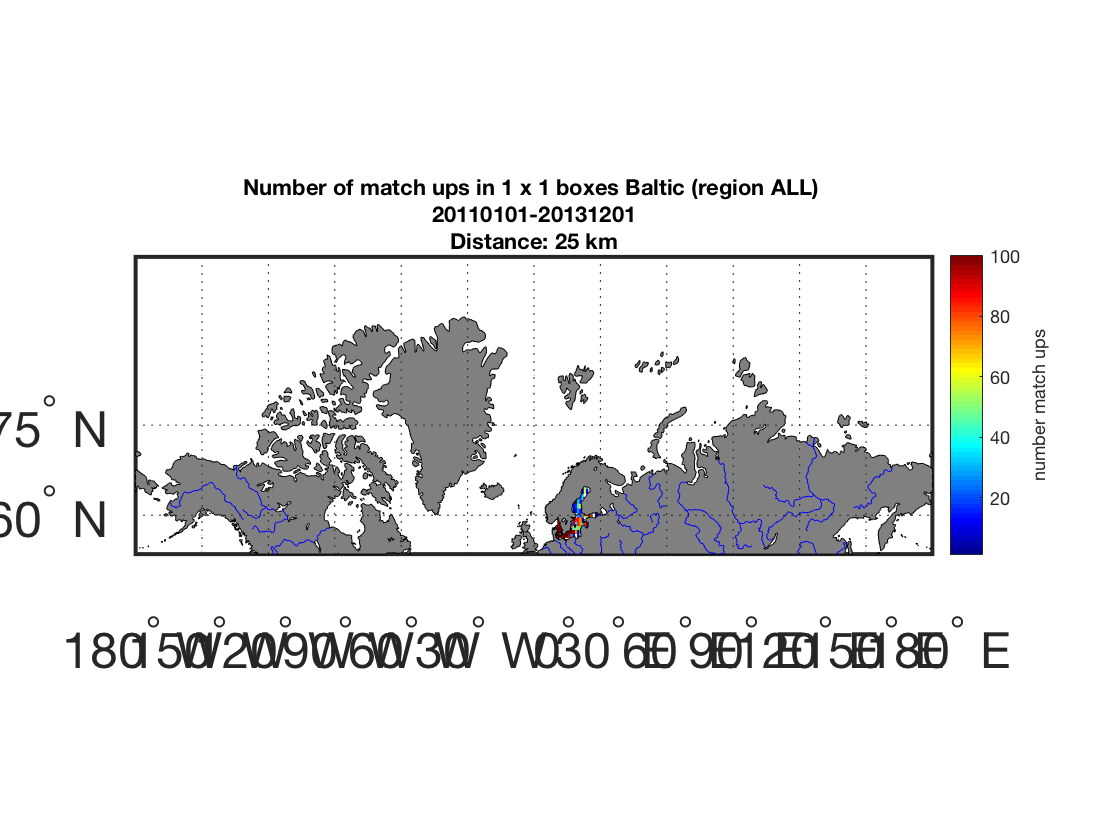

var_in = X1.SALT_ref;
lon_in = X1.lon_irange;
lat_in = X1.lat_irange;

bin_sz = 1; % bin size in degrees
[TT] = bindata_raf(ibasin,bin_sz,lon_in,lat_in,var_in);

bin_sz_str = num2str(bin_sz);
lon_bin = TT.lon_bin;
lat_bin = TT.lat_bin;
count_bin = TT.count_bin;
SALT_ref1_bin_mean = TT.mean_bin;
SALT_ref1_bin_median = TT.median_bin;

cmin = 1;
cmax = 100;

% set zero counts to NaN (to improve the pcolor plot)
ind = count_bin == 0;
count_bin(ind) = NaN;

time_line = linspace(time_start,time_end,ncount);

time_str1 = datestr(time_line(1),'yyyymmdd');
time_str2 = datestr(time_line(end),'yyyymmdd');

% make pcolor map
figure;
fillmap_arctic(1); hold on
pcolorm(lat_bin,lon_bin,count_bin); shading flat; fillmap_arctic(1);
colormap(jet)

ch = colorbar;
ylabel(ch,'number match ups')

caxis ([cmin cmax]);

title({...
    ['Number of match ups in ' bin_sz_str ' x ' bin_sz_str ' boxes ' basin_str ' (region ' region ') '];...
    [time_str1 '-' time_str2]
    ['Distance: ' num2str(r) ' km']});



fg_name = ['SDN_'...
    time_str1 '_' time_str2...
     '_BINNED_COUNTS_' region '_R' num2str(r) 'KM.'  fg_format];


% Save figure  - output -
folder_this = [folder_figs 'BINNED/COUNTS/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.2.1] TIMESERIES: ALL-SSS at ALL-float location

Compare each product to Salinity ref [0-10 m] average

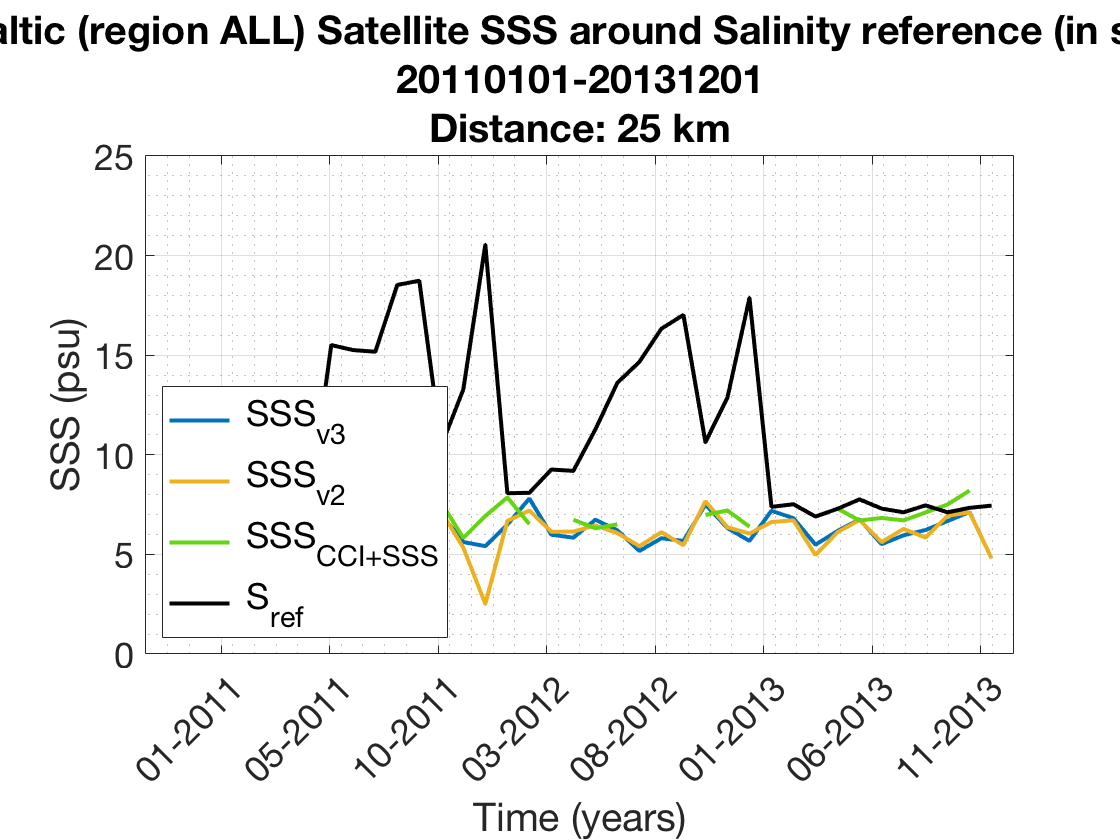

% string product name
PRODS = {...
    ' SSS_{v3}',' SSS_{v2}',' SSS_{CCI+SSS}',' S_{ref}'};

make_plot = 1;

if make_plot == 1
    % Get more colors: type 'uisetcolor'
    color_lines = [...
        0    0.4471    0.7412;...
        0.9294    0.6941    0.1255;...
        0.3922    0.8314    0.0745;...
        0.7176    0.2745    1.0000;...
        0.9294    0.6941    0.1255;...
        1.0000    0.0745    0.6510];
    
    time_line = linspace(time_start,time_end,ncount);
    
    time_str1 = datestr(time_line(1),'yyyymmdd');
    time_str2 = datestr(time_line(end),'yyyymmdd');
    
    Y_beta1 = sss_monthly_median1;
    Y_beta2 = sss_monthly_median2;
    Y_beta3 = sss_monthly_median3;
    Y_beta4 = SALT_ref_monthly_median1;
    
    Y_beta1 (Y_beta1 == 0) = NaN;
    Y_beta2 (Y_beta2 == 0) = NaN;
    Y_beta3 (Y_beta3 == 0) = NaN;
    Y_beta4 (Y_beta4 == 0) = NaN;
    
    % ==========================
     figure
    
    hold on
    
    h1 = plot(time_line,Y_beta1,'-','linewidth',2,'color',color_lines(1,:));hold on
    h2 = plot(time_line,Y_beta2,'-','linewidth',2,'color',color_lines(2,:));hold on
    h3 = plot(time_line,Y_beta3,'-','linewidth',2,'color',color_lines(3,:));hold on
    h4 = plot(time_line,Y_beta4,'-','linewidth',2,'color','k',...
        'MarkerFaceColor',color_lines(3,:));hold on
    
    xlabel ('Time (years)','fontsize',20)
    ylabel ('SSS (psu)','fontsize',20)
    
    grid on
    grid minor
    box on
    
    h = findobj(gca, 'type', 'text');
    set(h,'FontSize',25);
    set(h,'VerticalAlignment', 'middle');
    set(gca,'FontSize',18);
    
    time_line2 = time_line(1):150:time_line(end);
    
    xticks(time_line2)
    xticklabels(datestr(time_line2,'mm-yyyy'))
    xtickangle(45)
    
    lg = legend([h1,h2,h3,h4],PRODS,...
        'fontsize',18,'location','Southwest');
    
    title({...
        [basin_str ' (region ' region ') Satellite SSS around Salinity reference (in situ) '];...
        [time_str1 '-' time_str2]
        ['Distance: ' num2str(r) ' km']});

      
    fg_name = ['SDN_'...
    datestr(time_line(1),'yyyymmdd') '_'...
    datestr(time_line(end),'yyyymmdd') '_TIMESERIES_SSS_' region ...
    '_R' num2str(r) 'KM.'  fg_format];

    
    % Save figure  - output -
    folder_this = [folder_figs 'TIMESERIES/SSS/'];
    
    if fg_save == 1
        foldercheck_raf(folder_this); %! make folder_figs
    end
    
    fg_name = [folder_this fg_name];
    
    % check fn existence
    fg_exist = exist(fg_name,'file');
    
    if fg_save == 1 && fg_exist == 0
        save_raf(gcf,fg_name,fg_format); close
    end
end

## [2.2.2] Number of colocations dSSS

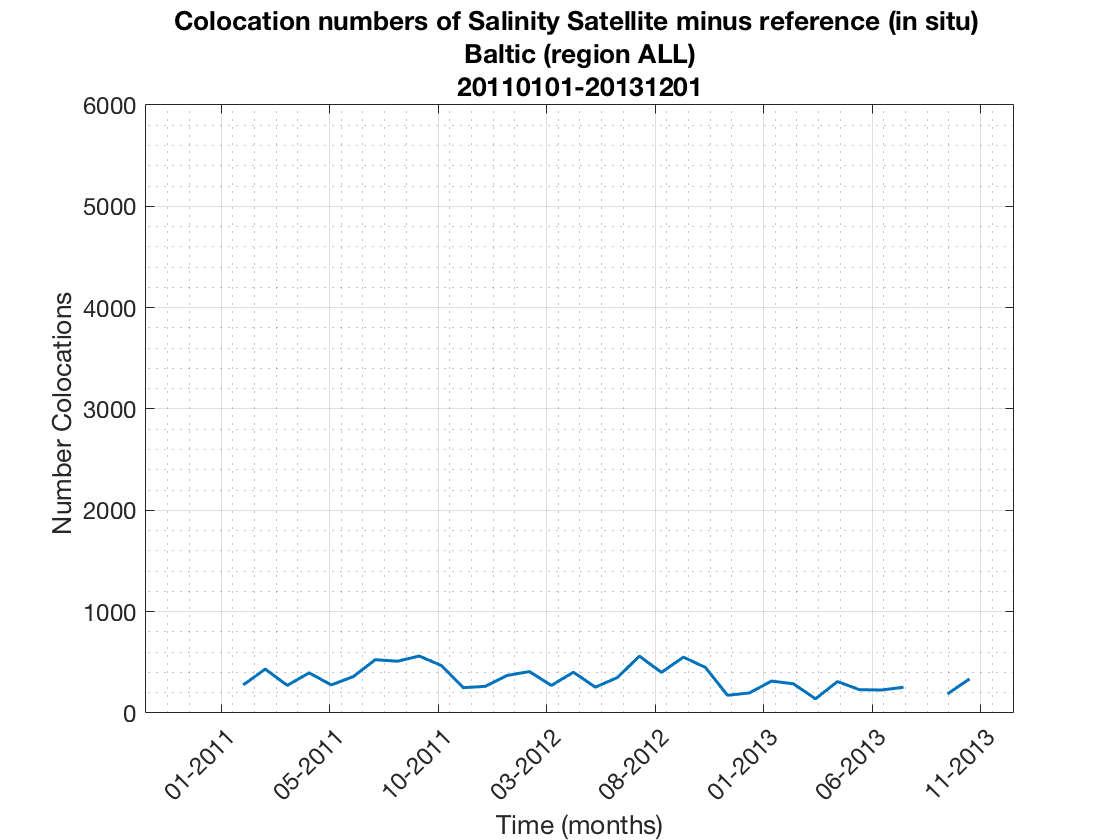

a_beta = ncoloc_monthly1;
b_beta = ncoloc_monthly2;
c_beta = ncoloc_monthly3;

a_beta (a_beta < std(ncoloc_monthly1)) = NaN;
b_beta (b_beta < std(ncoloc_monthly2)) = NaN;
c_beta (c_beta < std(ncoloc_monthly3)) = NaN;


ncoloc1_total = sum(ncoloc_monthly1);
ncoloc2_total = sum(ncoloc_monthly2);
ncoloc3_total = sum(ncoloc_monthly3);

% set the timeseries line
time_line = linspace(time_start,time_end,ncount);

time_str1 = datestr(time_line(1),'yyyymmdd');
time_str2 = datestr(time_line(end),'yyyymmdd');

STATS_vars = {...
    [' N colocations dSSS_{v3} [' num2str(ncoloc1_total) ']'],...
    [' N colocations dSSS_{v2} [' num2str(ncoloc2_total) ']'],...
    [' N colocations dSSS_{CCI+SSS} [' num2str(ncoloc3_total) ']'] };

X = X1.time_irange;

figure (25); clf; hold on
h1 = plot(time_line,a_beta,'-','MarkerFaceColor',color_lines(1,:),'linewidth',1.5); hold on

% h2 = plot(time_line,b_beta,'-','MarkerFaceColor',color_lines(2,:),'linewidth',1.5); hold on
% 
% h3 = plot(time_line,c_beta,'-','MarkerFaceColor',color_lines(4,:),'linewidth',1.5); hold on



% lg = legend([h1],STATS_vars{1},...
%    'fontsize',18,'location','SouthEast');

ylim([0 6000])

grid on
grid minor
box on

set(gca,'FontSize',12)

  time_line2 = time_line(1):150:time_line(end);
    
    xticks(time_line2)
    xticklabels(datestr(time_line2,'mm-yyyy'))
    xtickangle(45)
    
xlabel ('Time (months)','fontsize',20)
ylabel ('Number Colocations ','fontsize',20)

title({['Colocation numbers of Salinity Satellite minus reference (in situ) '];...
    [basin_str ' (region ' region ')'];...
    [datestr(time_line(1),'yyyymmdd') '-' datestr(time_line(end),'yyyymmdd')]})


% Save figure  - output -
fg_name = ['SDN'...
    datestr(time_line(1),'yyyymmdd') '_'...
    datestr(time_line(end),'yyyymmdd') '_TIMESERIES_dSSS_NCOLOC_' region '_'...
    '_R' num2str(r) 'KM.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TIMESERIES/dSSS/NCOLOC/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.2.3] MEAN dSSS

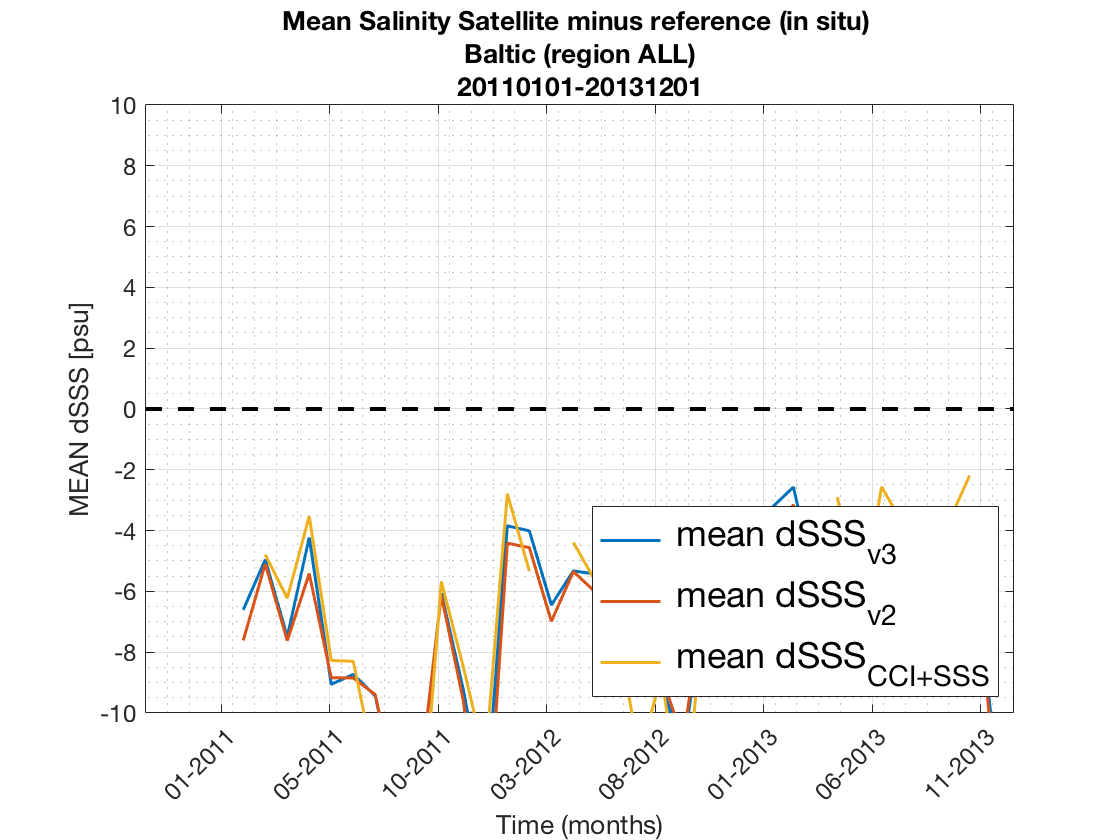

a_beta = dsss_monthly_mean1;
b_beta = dsss_monthly_mean2;
c_beta = dsss_monthly_mean3;


% set the timeseries line
time_line = linspace(time_start,time_end,ncount);

time_str1 = datestr(time_line(1),'yyyymmdd');
time_str2 = datestr(time_line(end),'yyyymmdd');

STATS_vars = {...
    ' mean dSSS_{v3}',...
    ' mean dSSS_{v2}',...
    ' mean dSSS_{CCI+SSS}'};

X = X1.time_irange;

figure (25); clf; hold on
%h1 = plot(X1.time_irange,Y1_mean,'.','color',[1 1 1].*.5); hold on
h1 = plot(time_line,a_beta,'-','MarkerFaceColor',color_lines(1,:),'linewidth',1.5); hold on


%figure (26); clf; hold on
h2 = plot(time_line,b_beta,'-','MarkerFaceColor',color_lines(2,:),'linewidth',1.5); hold on

% figure (27); clf; hold on
h3 = plot(time_line,c_beta,'-','MarkerFaceColor',color_lines(4,:),'linewidth',1.5); hold on


plot(xlim, [0 0],'k--','linewidth',2)

lg = legend([h1,h2,h3],STATS_vars{:},...
   'fontsize',18,'location','SouthEast');

ylim([-1 1].*10)

grid on
grid minor
box on

set(gca,'FontSize',12)

  time_line2 = time_line(1):150:time_line(end);
    
  xticks(time_line2)
  xticklabels(datestr(time_line2,'mm-yyyy'))
  xtickangle(45)
    
xlabel ('Time (months)','fontsize',20)
ylabel ('MEAN dSSS [psu]','fontsize',20)

title({['Mean Salinity Satellite minus reference (in situ) '];...
    [basin_str ' (region ' region ')'];...
    [datestr(time_line(1),'yyyymmdd') '-' datestr(time_line(end),'yyyymmdd')]})


% Save figure  - output -
fg_name = ['SDN'...
    datestr(time_line(1),'yyyymmdd') '_'....
    datestr(time_line(end),'yyyymmdd') '_TIMESERIES_dSSS_MEAN_' region '_'  ...
    '_R' num2str(r) 'KM.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TIMESERIES/dSSS/MEAN/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.2.4] TIMESERIES STD SSS -BUG to fix (desc: not sure if bug, but time series of different product are too similar to each other)

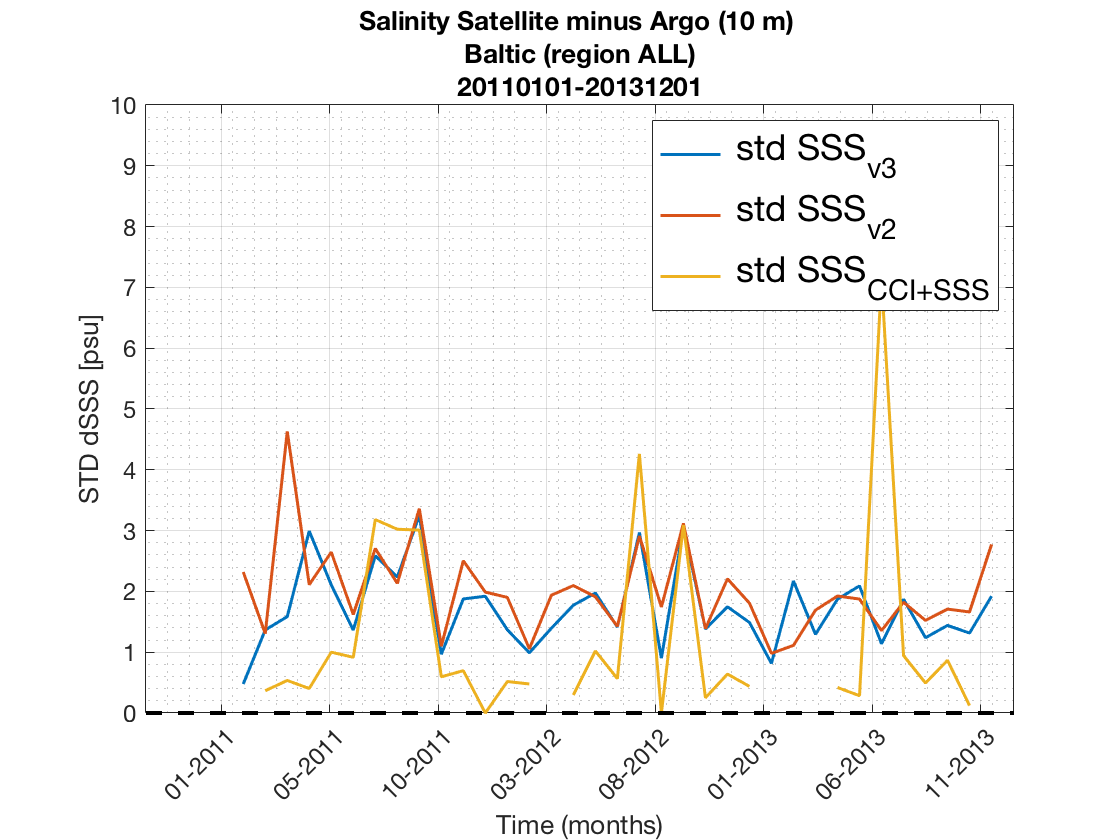

make_plot = 1;

if make_plot == 1
a_beta = sss_monthly_std1;
b_beta = sss_monthly_std2;
c_beta = sss_monthly_std3;


% set the timeseries line
time_line = linspace(time_start,time_end,ncount);

time_str1 = datestr(time_line(1),'yyyymmdd');
time_str2 = datestr(time_line(end),'yyyymmdd');

STATS_vars = {...
    ' std SSS_{v3}',...
    ' std SSS_{v2}',...
    ' std SSS_{CCI+SSS}'};

X = X1.time_irange;

figure (25); clf; hold on
%h1 = plot(X1.time_irange,Y1_mean,'.','color',[1 1 1].*.5); hold on
h1 = plot(time_line,a_beta,'-','MarkerFaceColor',color_lines(1,:),'linewidth',1.5); hold on


%figure (26); clf; hold on
h2 = plot(time_line,b_beta,'-','MarkerFaceColor',color_lines(2,:),'linewidth',1.5); hold on

% figure (27); clf; hold on
h3 = plot(time_line,c_beta,'-','MarkerFaceColor',color_lines(4,:),'linewidth',1.5); hold on


plot(xlim, [0 0],'k--','linewidth',2)

lg = legend([h1,h2,h3],STATS_vars{:},...
   'fontsize',18,'location','NorthEast');

ylim([0 1].*10)

grid on
grid minor
box on

set(gca,'FontSize',12)

time_line2 = time_line(1):150:time_line(end);

xticks(time_line2)
xticklabels(datestr(time_line2,'mm-yyyy'))
xtickangle(45)
    
xlabel ('Time (months)','fontsize',20)
ylabel ('STD dSSS [psu]','fontsize',20)

title({['Salinity Satellite minus Argo (10 m) '];...
    [basin_str ' (region ' region ')'];...
    [datestr(time_line(1),'yyyymmdd') '-' datestr(time_line(end),'yyyymmdd')]})

% Save figure  - output -
fg_name = ['SDN'...
    datestr(time_line(1),'yyyymmdd') '_'....
    datestr(time_line(end),'yyyymmdd') '_TIMESERIES_dSSS_STD_' region '_'...
    '_R' num2str(r) 'KM.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TIMESERIES/dSSS/STD/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

end

## [2.2.5] TIMESERIES MEDIAN dSSS

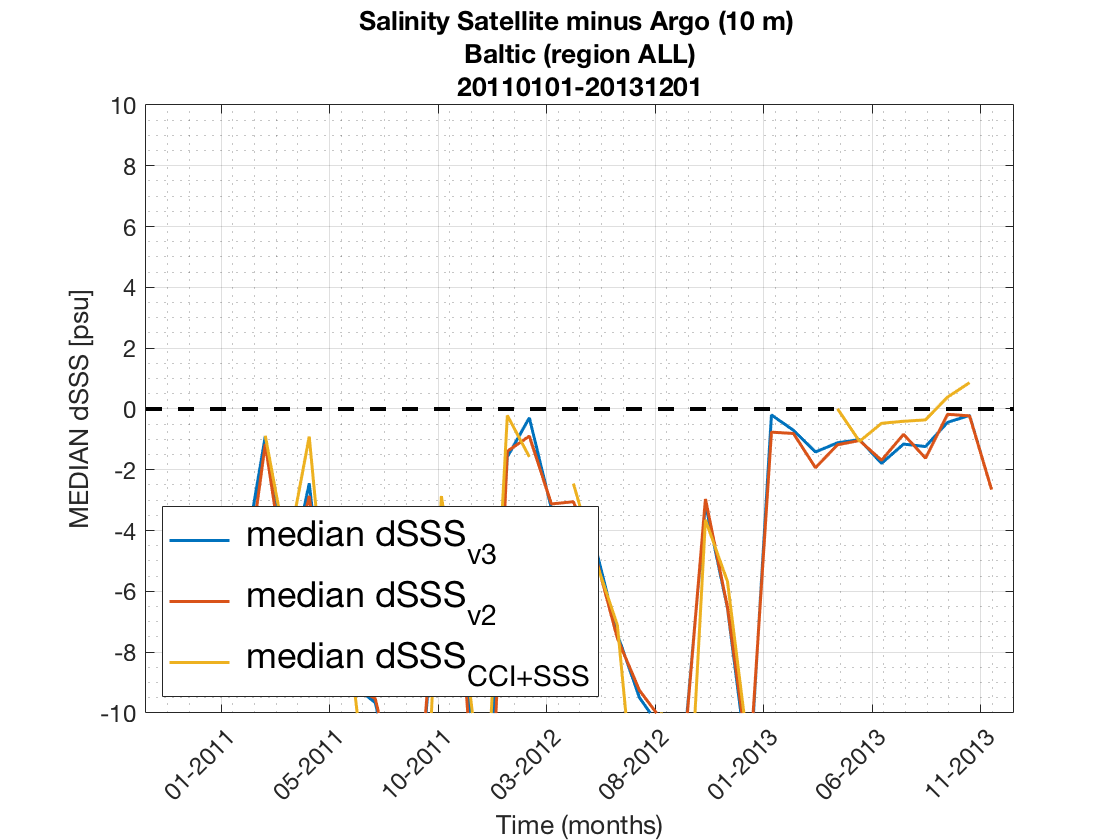

a_beta = dsss_monthly_median1;
b_beta = dsss_monthly_median2;
c_beta = dsss_monthly_median3;


% set the timeseries line
time_line = linspace(time_start,time_end,ncount);

time_str1 = datestr(time_line(1),'yyyymmdd');
time_str2 = datestr(time_line(end),'yyyymmdd');

STATS_vars = {...
    ' median dSSS_{v3}',...
    ' median dSSS_{v2}',...
    ' median dSSS_{CCI+SSS}'};

X = X1.time_irange;

figure (25); clf; hold on
%h1 = plot(X1.time_irange,Y1_mean,'.','color',[1 1 1].*.5); hold on
h1 = plot(time_line,a_beta,'-','MarkerFaceColor',color_lines(1,:),'linewidth',1.5); hold on


%figure (26); clf; hold on
h2 = plot(time_line,b_beta,'-','MarkerFaceColor',color_lines(2,:),'linewidth',1.5); hold on

% figure (27); clf; hold on
h3 = plot(time_line,c_beta,'-','MarkerFaceColor',color_lines(4,:),'linewidth',1.5); hold on


plot(xlim, [0 0],'k--','linewidth',2)

lg = legend([h1,h2,h3],STATS_vars{:},...
   'fontsize',18,'location','SouthWest');

ylim([-1 1].*10)

grid on
grid minor
box on

set(gca,'FontSize',12)

  time_line2 = time_line(1):150:time_line(end);
    
    xticks(time_line2)
    xticklabels(datestr(time_line2,'mm-yyyy'))
    xtickangle(45)
    
xlabel ('Time (months)','fontsize',20)
ylabel ('MEDIAN dSSS [psu]','fontsize',20)

title({['Salinity Satellite minus Argo (10 m) '];...
    [basin_str ' (region ' region ')'];...
    [datestr(time_line(1),'yyyymmdd') '-' datestr(time_line(end),'yyyymmdd')]})


% Save figure  - output -
fg_name = ['SDN'...
    datestr(time_line(1),'yyyymmdd') '_'....
    datestr(time_line(end),'yyyymmdd') '_TIMESERIES_dSSS_MEDIAN_' region '_'...
    '_R' num2str(r) 'KM.'  fg_format];

% Save figure  - output -
folder_this = [folder_figs 'TIMESERIES/dSSS/MEDIAN/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.3] BOXPLOTS

## [2.3.1] boxplots: ALL Argo data versus ALL Satellite data

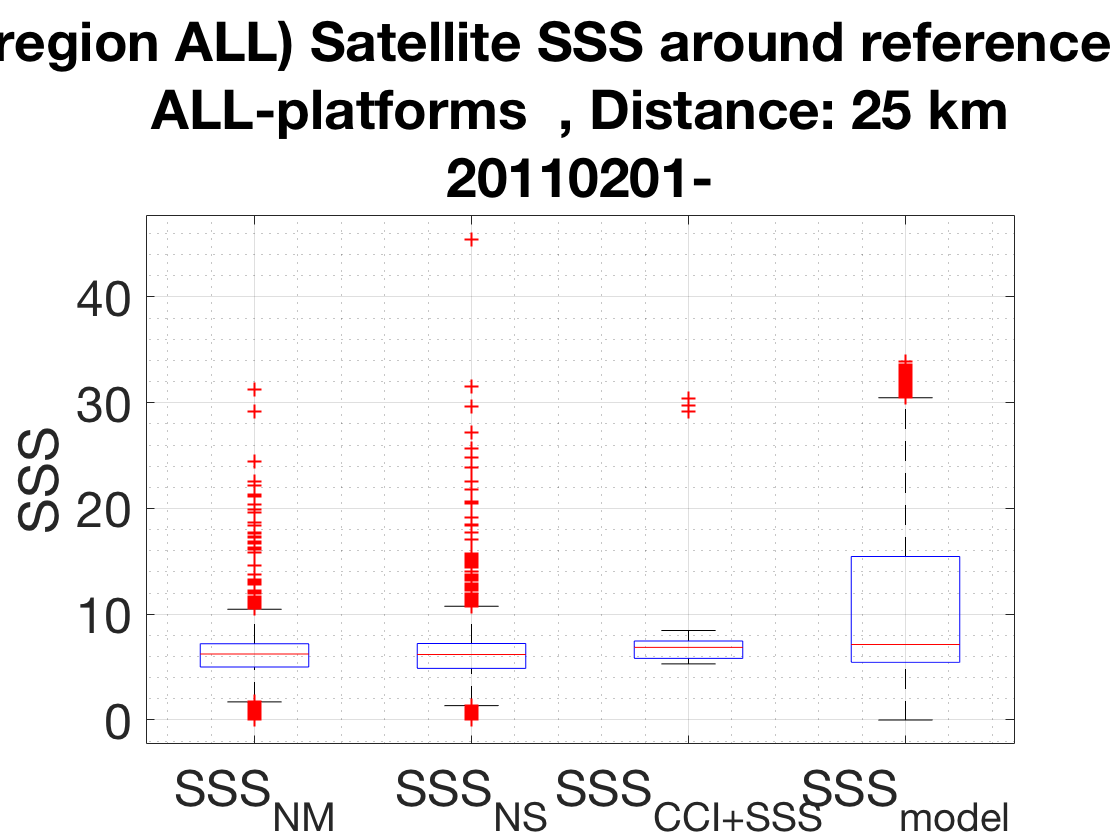

make_plot = 1; % flag to make plot [1], or not [0]
if make_plot == 1
    % string product name
    PRODS = {'SSS_{NM}',...
        'SSS_{NS}',...
        'SSS_{CCI+SSS}',...
        'SSS_{model}'};
    
    nprof1 = length(X1.lon_irange);
    nprof2 = length(X2.lon_irange);
    nprof3 = length(X3.lon_irange);
    nprof4 = length(X4.lon_irange);

    
    time_ar = X1.time_irange(:);
    
    ind = ~isnan(time_ar);
    
    time_str1 = datestr(time_ar(ind(1)),'yyyymmdd');
    time_str2 = datestr(time_ar(ind(end)),'yyyymmdd');
    
    
    X1_beta = X1.sss_irange(:);
    X2_beta = X2.sss_irange(:);
    X3_beta = X3.sss_irange(:);
    X4_beta = X4.sss_irange(:);

    
    X1_beta = X1_beta(:);
    X2_beta = X2_beta(:);
    X3_beta = X3_beta(:);
    X4_beta = X4_beta(:);

    
    X1_beta(X1_beta == 0) = NaN;
    X2_beta(X2_beta == 0) = NaN;
    X3_beta(X3_beta == 0) = NaN;
    X4_beta(X3_beta == 0) = NaN;

    
    figure; clf; hold on;
    set(gcf,'DefaultAxesFontSize',24);
    
    C = {X1_beta(:),X2_beta(:),X3_beta(:),X4_beta(:)};
    grp = cell2mat(arrayfun(@(i){i*ones(numel(C{i}),1)},(1:numel(C))')); 
    
    bplot = boxplot(vertcat(C{:}),grp,'labels',PRODS);
    
    bp = gca;
    bp.XAxis.TickLabelInterpreter = 'tex';
    
    %ylim([0 15]);
    
    ylabel('SSS')
    
    grid on
    grid minor
    
    h = findobj(gca, 'type', 'text');
    set(h,'FontSize',25);
    set(h,'VerticalAlignment', 'middle');
    set(gca,'FontSize',25);
    
    title({...
        [basin_str '(region ' region ') Satellite SSS around reference (in situ) '];...
        ['ALL-platforms  '...
        ', Distance: ' num2str(r) ' km'];...
        [time_str1 '-' time_str2]});
    
    fg_name = ['SDN' ...
        '_SAT-SSS_BOXPLOT_' region '_'...
        time_str1 '_' time_str2...
        '_R' num2str(r) 'KM.'...
        fg_format];
    
    % Save figure  - output -
    folder_this = [folder_figs 'BOXPLOTS/'];
    
    if fg_save == 1
        foldercheck_raf(folder_this); %! make folder_figs
    end
    
    fg_name = [folder_this fg_name];
    
    
    fg_exist = exist(fg_name,'file'); % check fn existence
    
    if fg_save == 1 && fg_exist == 0
        save_raf(gcf,fg_name,fg_format); close
    end
    
end; clear ind *beta* *exist*

## [2.4] Histograms of dSSS

a_beta = X1.dSSS_irange;
b_beta = X2.dSSS_irange;
c_beta = X3.dSSS_irange;
d_beta = X4.dSSS_irange;

a_beta(isnan(a_beta)) = [];
b_beta(isnan(b_beta)) = [];
c_beta(isnan(c_beta)) = [];
d_beta(isnan(d_beta)) = [];

a_beta = nanmean(a_beta,1);
b_beta = nanmean(b_beta,1);
c_beta = nanmean(c_beta,1);
d_beta = nanmean(d_beta,1);

time_a = X1.time_irange;
time_b = X2.time_irange;
time_c = X3.time_irange;
time_d = X4.time_irange;

time_a(isnan(time_a)) = [];
time_b(isnan(time_b)) = [];
time_c(isnan(time_c)) = [];
time_d(isnan(time_d)) = [];


% set the maximun dSSS to set limits xaxis in histograms

CORRECT = 1; % flag to [1] remove outlier (above dSSS_max), or not [0]

if CORRECT == 1
    
    CORRECT_str = 'FILTERED';
    
    dSSS_max = 10;
    
    ind_a = abs(a_beta)>dSSS_max;
    ind_b = abs(b_beta)>dSSS_max;
    ind_c = abs(c_beta)>dSSS_max;
    ind_d = abs(d_beta)>dSSS_max;

    
    % remove values above dSSS
    a_beta(ind_a) =[];
    b_beta(ind_b) =[];
    c_beta(ind_c) =[];
    d_beta(ind_d) =[];
    
elseif CORRECT == 0
    CORRECT_str = 'NoFilter';
    
    dSSS_max = 40;

    
end

## [2.4.1] Baltic+ v3.0 Compute stats for dSSS

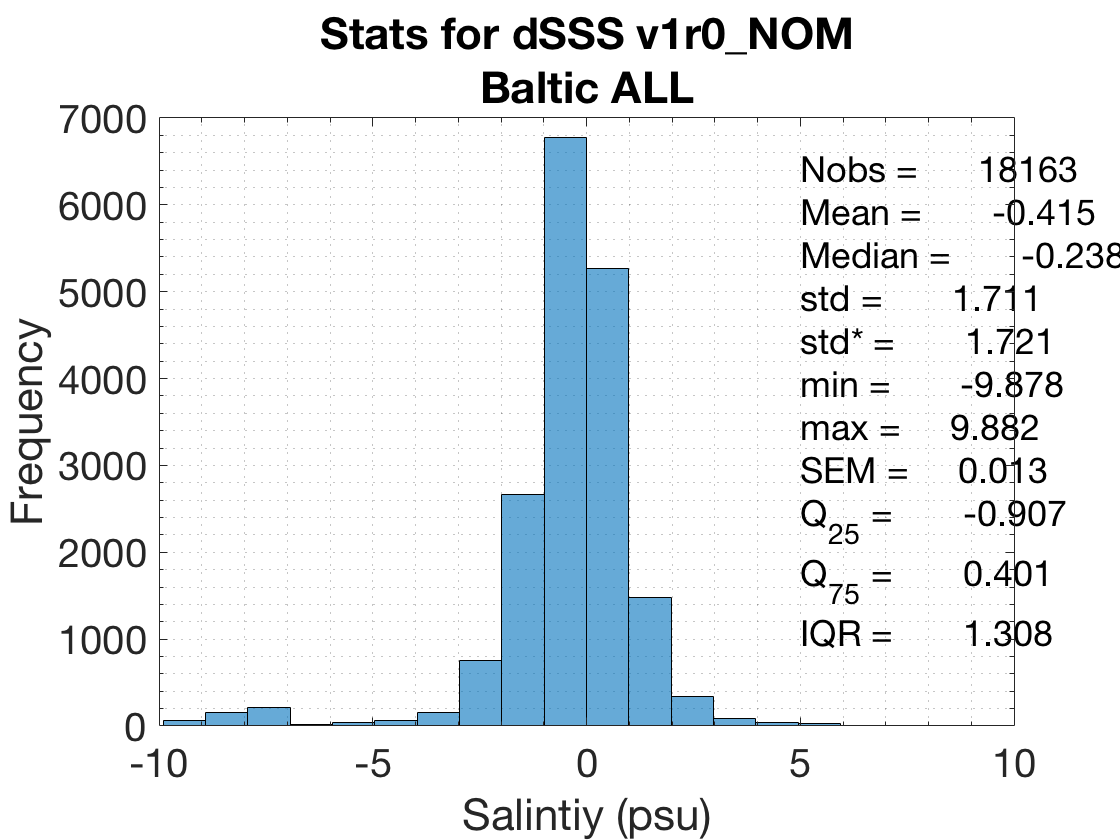

[X1_mean,X1_median,X1_std,X1_stdRobust,X1_min,X1_max,...
    X1_SEM,Q,X1_Q2,X1_Q4,X1_IQR,STATS_str]...
    = validation_stats(a_beta);

figure
nbins = 20;

histogram(a_beta,nbins)
[N,edges] = histcounts(a_beta,nbins);
xlim ([-1 1].*dSSS_max)

box on
set(gca,'XMinorTick','on','YMinorTick','on')

ylim_beta=get(gca,'ylim');
xlim_beta=get(gca,'xlim');

h1 = text(xlim_beta(2)*.5,ylim_beta(2)*.5,sprintf('%s\n',STATS_str{:}),'fontsize',18);

grid minor

set(gca,'FontSize',20)

title({['Stats for dSSS ' X1.version_str ],...
    [basin_str ' ' region]},...
    'fontsize',24,'interpreter','none');

xlabel('Salintiy (psu)','fontsize',24);
ylabel([ 'Frequency' ], 'fontsize',24);


% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_a(1),'yyyymmdd') '_'....
    datestr(time_a(end),'yyyymmdd') '_HISTOGRAMS_dSSS_' region '_'...
    X1.version_str '_R' num2str(r) 'KM.'  fg_format];
    

% Save figure  - output -
folder_this = [folder_figs 'HISTOGRAMS/dSSS/' CORRECT_str '/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.4.2] Baltic v2.0 Compute stats for dSSS

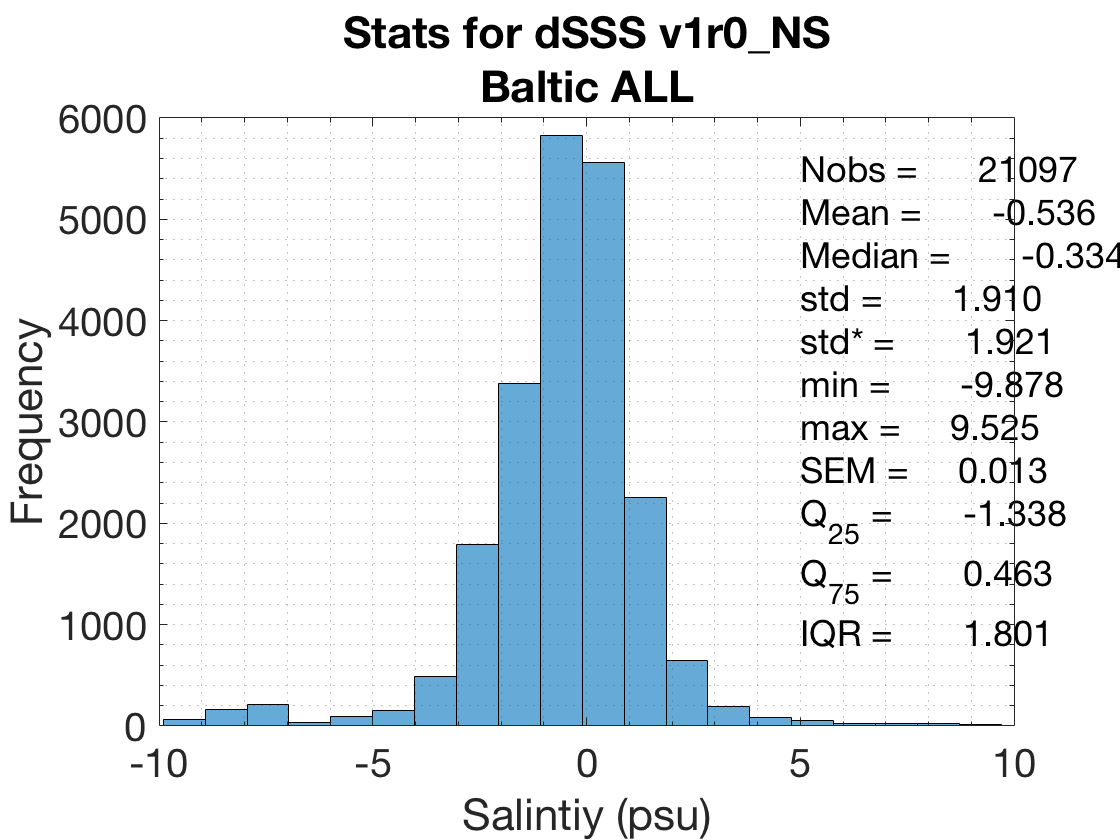

[X1_mean,X1_median,X1_std,X1_stdRobust,X1_min,X1_max,...
    X1_SEM,Q,X1_Q2,X1_Q4,X1_IQR,STATS_str]...
    = validation_stats(b_beta);

figure
histogram(b_beta,nbins)
[N,edges] = histcounts(b_beta,nbins);
xlim ([-1 1].*dSSS_max)

box on
set(gca,'XMinorTick','on','YMinorTick','on')

ylim_beta=get(gca,'ylim');
xlim_beta=get(gca,'xlim');

h1 = text(xlim_beta(2)*.5,ylim_beta(2)*.5,sprintf('%s\n',STATS_str{:}),'fontsize',18);

grid minor

set(gca,'FontSize',20)

title({['Stats for dSSS ' X2.version_str ],...
    [basin_str ' ' region]},...
    'fontsize',24,'interpreter','none');

xlabel('Salintiy (psu)','fontsize',24);
ylabel([ 'Frequency' ], 'fontsize',24);


% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_b(1),'yyyymmdd') '_'....
    datestr(time_b(end),'yyyymmdd') '_HISTOGRAMS_dSSS_' region '_'...
    X2.version_str '_R' num2str(r) 'KM.'  fg_format];
    

% Save figure  - output -
folder_this = [folder_figs 'HISTOGRAMS/dSSS/' CORRECT_str '/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.4.3] CCI+SSS Compute stats for dSSS

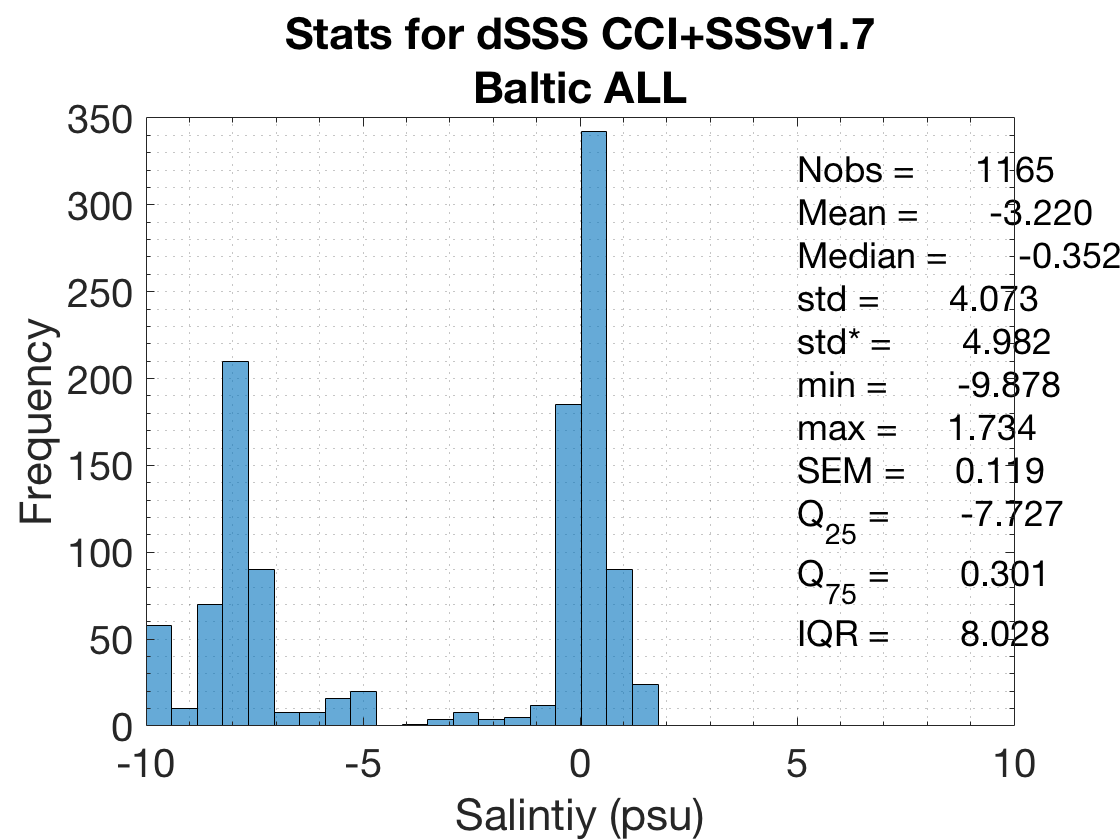

[X1_mean,X1_median,X1_std,X1_stdRobust,X1_min,X1_max,...
    X1_SEM,Q,X1_Q2,X1_Q4,X1_IQR,STATS_str]...
    = validation_stats(c_beta);

figure
histogram(c_beta,nbins)
[N,edges] = histcounts(c_beta,nbins);
xlim ([-1 1].*dSSS_max)

box on
set(gca,'XMinorTick','on','YMinorTick','on')

ylim_beta=get(gca,'ylim');
xlim_beta=get(gca,'xlim');

h1 = text(xlim_beta(2)*.5,ylim_beta(2)*.5,sprintf('%s\n',STATS_str{:}),'fontsize',18);

grid minor

set(gca,'FontSize',20)

title({['Stats for dSSS ' X3.version_str ],...
    [basin_str ' ' region]},...
    'fontsize',24,'interpreter','none');

xlabel('Salintiy (psu)','fontsize',24);
ylabel([ 'Frequency' ], 'fontsize',24);



% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_c(1),'yyyymmdd') '_'....
    datestr(time_c(end),'yyyymmdd') '_HISTOGRAMS_dSSS_' region '_'...
    X3.version_str '_R' num2str(r) 'KM.'  fg_format];
    

% Save figure  - output -
folder_this = [folder_figs 'HISTOGRAMS/dSSS/' CORRECT_str '/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.4.3] CCI+SSS Compute stats for dSSS

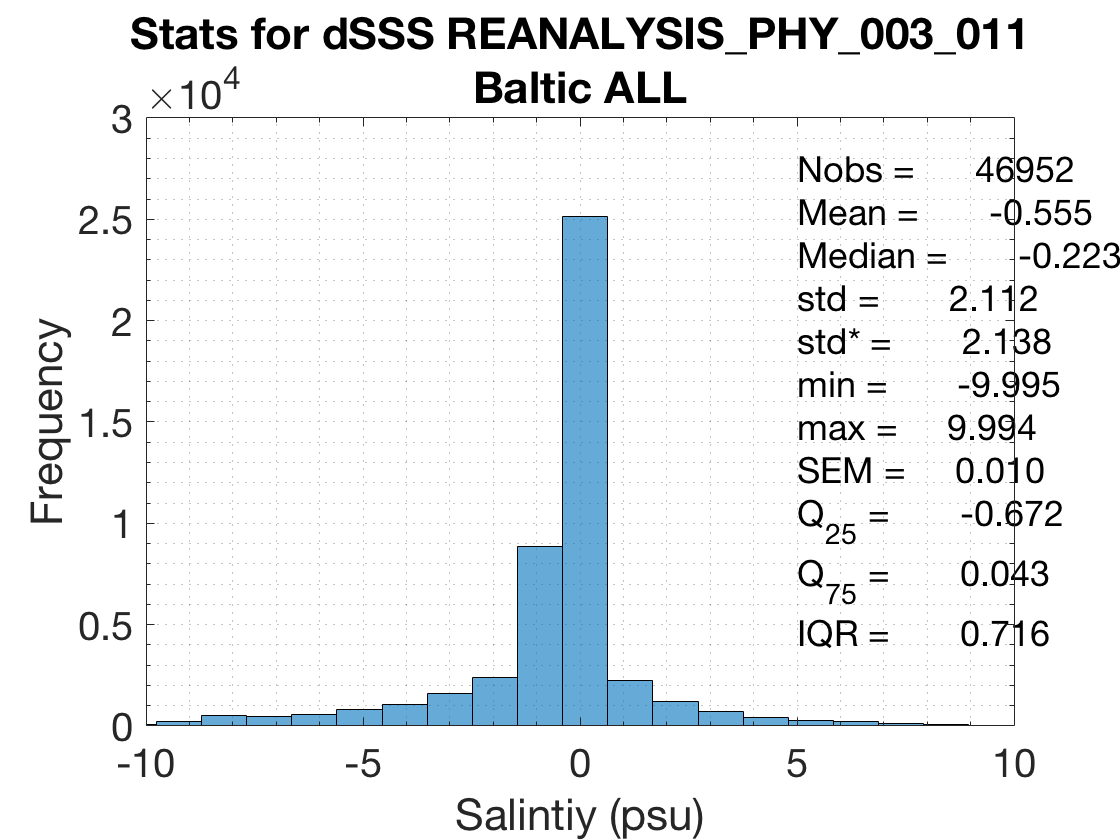

[X1_mean,X1_median,X1_std,X1_stdRobust,X1_min,X1_max,...
    X1_SEM,Q,X1_Q2,X1_Q4,X1_IQR,STATS_str]...
    = validation_stats(d_beta);

figure
histogram(d_beta,nbins)
[N,edges] = histcounts(d_beta,nbins);
xlim ([-1 1].*dSSS_max)

box on
set(gca,'XMinorTick','on','YMinorTick','on')

ylim_beta=get(gca,'ylim');
xlim_beta=get(gca,'xlim');

h1 = text(xlim_beta(2)*.5,ylim_beta(2)*.5,sprintf('%s\n',STATS_str{:}),'fontsize',18);

grid minor

set(gca,'FontSize',20)

title({['Stats for dSSS ' X4.version_str ],...
    [basin_str ' ' region]},...
    'fontsize',24,'interpreter','none');

xlabel('Salintiy (psu)','fontsize',24);
ylabel([ 'Frequency' ], 'fontsize',24);



% Save figure  - output -
fg_name = ['SDN_'...
    datestr(time_d(1),'yyyymmdd') '_'....
    datestr(time_d(end),'yyyymmdd') '_HISTOGRAMS_dSSS_' region '_'...
    X4.version_str '_R' num2str(r) 'KM.'  fg_format];
    

% Save figure  - output -
folder_this = [folder_figs 'HISTOGRAMS/dSSS/' CORRECT_str '/'];

if fg_save == 1
    foldercheck_raf(folder_this); %! make folder_figs
end

fg_name = [folder_this fg_name];

% check fn existence
fg_exist = exist(fg_name,'file');

if fg_save == 1 && fg_exist == 0
    save_raf(gcf,fg_name,fg_format); close
end

## [2.7] TAYLOR DIAGRAMS - NOT WORKING

% % Compute stats to include in Taylor diagram using Argo_10m % (averaged surface) as the reference measure % (use function: 'allstats') % TAYLOR diagrram inputs: % [1] STDs: Standard deviations % [2] RMSs: Centered Root Mean Square Difference % [3] CORs: Correlation

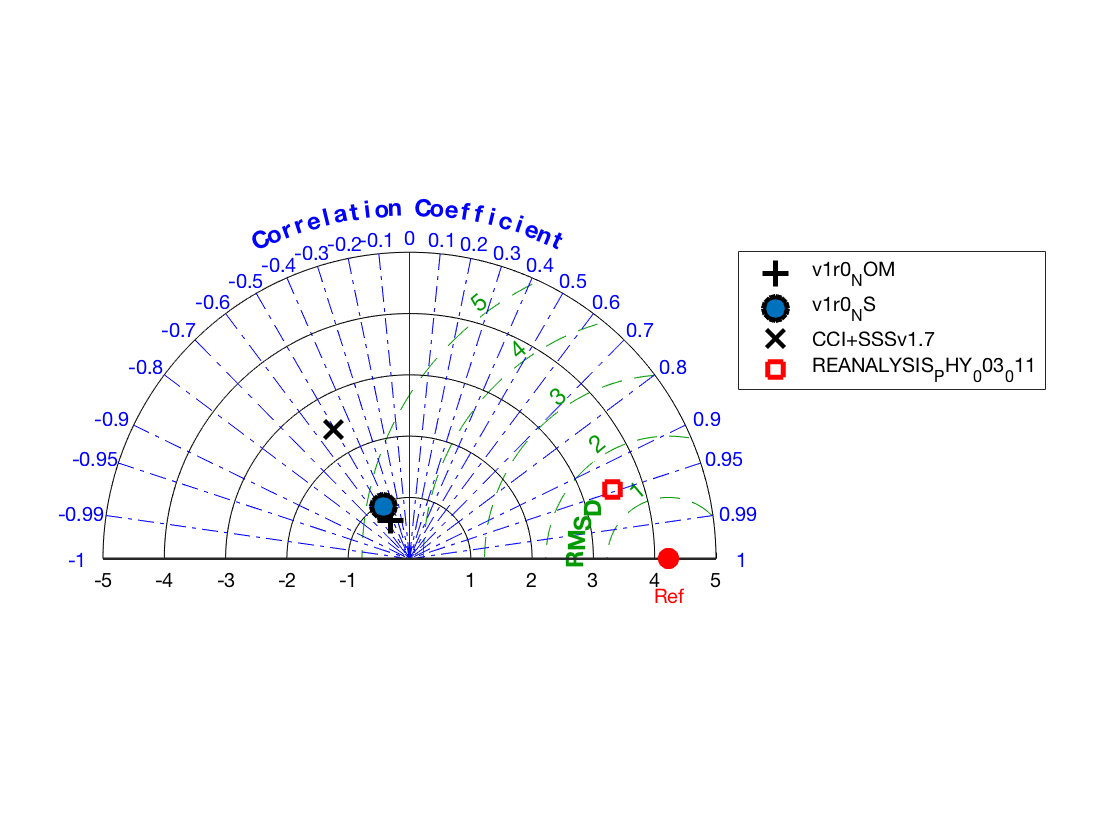

% make homogeneous matrices (ie. equal dimensions)
X_ref1 = nan(1,3e6);
X_ref2 = nan(1,3e6);
X_ref3 = nan(1,3e6);
X_ref4 = nan(1,3e6);


Y1 = nan(1,3e6);
Y2 = nan(1,3e6);
Y3 = nan(1,3e6);
Y4 = nan(1,3e6);


% % Use monthly values as computed in section 1
[~,Ln1] = size(SALT_ref_monthly_median1);
[~,Ln2] = size(SALT_ref_monthly_median2);
[~,Ln3] = size(SALT_ref_monthly_median3);
[~,Ln4] = size(SALT_ref_monthly_median4);

X_ref1(1,1:Ln1) = SALT_ref_monthly_median1; % reference salinity
X_ref2(1,1:Ln2) = SALT_ref_monthly_median2;
X_ref3(1,1:Ln3) = SALT_ref_monthly_median3;
X_ref4(1,1:Ln4) = SALT_ref_monthly_median4;


Y1(1,1:Ln1) = sss_monthly_median1;
Y2(1,1:Ln2) = sss_monthly_median2;
Y3(1,1:Ln3) = sss_monthly_median3;
Y4(1,1:Ln4) = sss_monthly_median4;


% index numbers elements in variables
ind1 = ~isnan(X_ref1) & ~isnan(X_ref2) & ~isnan(X_ref3) & ~isnan(X_ref4);
ind2 = ~isnan(Y1) & ~isnan(Y2) & ~isnan(Y3) & ~isnan(Y4);

% indx common element between ref and testing datasets
ind = ind1 & ind2;

% Get the one singe reference dataset (i.e. Argo, SDN, etc.)
X_ref = [X_ref1(ind); X_ref2(ind); X_ref3(ind); X_ref4(ind)];
X_ref = nanmedian(X_ref,1);

Y1 = Y1(ind);
Y2 = Y2(ind);
Y3 = Y3(ind);
Y4 = Y4(ind);


% =========================
Y1_STATS = allstats(X_ref,Y1);
Y2_STATS = allstats(X_ref,Y2);
Y3_STATS = allstats(X_ref,Y3);
Y4_STATS = allstats(X_ref,Y4);


X_ref_STATS = Y1_STATS(:,1);

Y1_STATS = Y1_STATS(:,2);
Y2_STATS = Y2_STATS(:,2);
Y3_STATS = Y3_STATS(:,2);
Y4_STATS = Y4_STATS(:,2);


% standard deviation
n = 2;
STD_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n),...
    Y4_STATS(n)]; clear n

% Root Mean Square
n = 3;
RMS_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n),...
    Y4_STATS(n)]; clear n

% Correlation
n = 4;
CORR_ALL = [...
    X_ref_STATS(n)...
    Y1_STATS(n)...
    Y2_STATS(n)...
    Y3_STATS(n),...
    Y4_STATS(n)]; clear n

label ={'ref',X1.version_str,X2.version_str,X3.version_str,X4.version_str};


figure(22); clf
[hp2, ht2, axl2] = taylor_diagram(STD_ALL,RMS_ALL,CORR_ALL,...
    'numberPanels',2,...
    'MarkerDisplayed','marker','alpha',.2,...
    'titleOBS','Ref','colOBS','r', 'markerObs','o',...
    'markerLabel',label, 'markerLegend', 'on',...
    'styleSTD', '-',...
    'titleRMS','on',...
    'checkStats','off');


marker_size = 12;
set(hp2(1),'MarkerEdgeColor','k',...
    'MarkerFaceColor','r','MarkerSize',marker_size)
set(hp2(2),'MarkerEdgeColor','k',...
    'MarkerFaceColor',color_lines(1,:),'MarkerSize',marker_size)
set(hp2(3),'MarkerEdgeColor','k',...
    'MarkerFaceColor',color_lines(2,:),'MarkerSize',marker_size)



% % % % 
% % % % =================
% % % % figure
% % % % output taylor
% % % % hp: handle for each point
% % % % ht: handle for each text
% % % % axl: handle for axis
% % % % [hp ht axl] = taylordiag(STD_ALL,RMS_ALL,CORR_ALL);
% % % % 
% % % % [hp ht axl] = taylordiag(Y1_STATS(2,2),Y1_STATS(3,2),Y1_STATS(4,2));
% % % % 
% % % % hold on
% % % % 
% % % % 
% % % % 
% % % % marker_size = 20;
% % % % 
% % % % set(hp(1),'marker','o','MarkerEdgeColor','k',...
% % % %     'MarkerFaceColor','r','MarkerSize',marker_size)
% % % % set(hp(2),'marker','o','MarkerEdgeColor','k',...
% % % %     'MarkerFaceColor',color_lines(1,:),'MarkerSize',marker_size)
% % % % set(hp(3),'marker','o','MarkerEdgeColor','k',...
% % % %     'MarkerFaceColor',color_lines(2,:),'MarkerSize',marker_size)
% % % % set(hp(4),'marker','o','MarkerEdgeColor','k',...
% % % %     'MarkerFaceColor',color_lines(4,:),'MarkerSize',marker_size)
% % % % 
% % % % 
% % % % set(ht(1),'color','r','fontsize',18,'verticalalignment','bottom')
% % % % set(ht(2),'color','k','fontsize',18)
% % % % set(ht(3),'color','k','fontsize',18)
% % % % set(ht(4),'color','k','fontsize',18)
% % % % 
% % % % lg = legend(hp,{' [A] Argo_{10m} (reference)',' [B] v3.0',' [C] v2.0',' [D] CCI+SSS'},...
% % % %     'Location','NorthEastOutside','fontsize',18);
% % % % 
% % % % make legend square bigger
% % % % (https://uk.mathworks.com/matlabcentral/answers/420941-how-can-i-enlarge-the-height-of-legend-box)
% % % % lg.Position(1) = 0.80; % move legend left/right [0-1]
% % % % lg.Position(2) = 0.70; % move legend down/up [0-1]
% % % % lg.Position(3) = 0.20; % move text in legend left/right [0-1]
% % % % lg.Position(4) = 0.30; % increase/decrease legend box [0-1]
% % % % 
% % % % 
% % % % Save figure  - output -
% % % % fg_name = ['SDN'...
% % % %     datestr(time_range(1),'yyyymmdd') '_'....
% % % %     datestr(time_range(end),'yyyymmdd') '_TAYLOR_SSS' ...
% % % %     '.'  fg_format];
% % % % 
% % % % Save figure  - output -
% % % % folder_this = [folder_figs 'TAYLOR/SSS/'];
% % % % 
% % % % if fg_save == 1
% % % %     foldercheck_raf(folder_this); %! make folder_figs
% % % % end
% % % % 
% % % % fg_name = [folder_this fg_name];
% % % % 
% % % % check fn existence
% % % % fg_exist = exist(fg_name,'file');
% % % % 
% % % % if fg_save == 1 && fg_exist == 0
% % % %     save_raf(gcf,fg_name,fg_format); close
% % % % end
% % % % 







% END-OF-SCRIPT